## Plot Y25747 Fern dataset

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Import data from xlsx

filename = 'Y25747_Fern_dataset.xlsx';
excelData = readtable(filename, 'Sheet', 'Y25747_Fern', 'VariableNamingRule', 'preserve');
numericData = table2array(excelData(1:end,2:20));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Extract all Y3650 + phage Fern dilutions
Time = numericData(:,1); % Time

Ctrl_rep_1 = numericData(:,2);
Ctrl_rep_2 = numericData(:,3);
Ctrl_rep_3 = numericData(:,4);

X5_rep_1 = numericData(:,5);
X5_rep_2 = numericData(:,6);
X5_rep_3 = numericData(:,7);

X6_rep_1 = numericData(:,8);
X6_rep_2 = numericData(:,9);
X6_rep_3 = numericData(:,10);

X7_rep_1 = numericData(:,11);
X7_rep_2 = numericData(:,12);
X7_rep_3 = numericData(:,13);

X8_rep_1 = numericData(:,14);
X8_rep_2 = numericData(:,15);
X8_rep_3 = numericData(:,16);

X9_rep_1 = numericData(:,17);
X9_rep_2 = numericData(:,18);
X9_rep_3 = numericData(:,19);

Low_Group = mean([Ctrl_rep_1,Ctrl_rep_2,Ctrl_rep_3,...
                  X9_rep_1,X9_rep_2,X9_rep_3,...
                  X8_rep_1,X8_rep_2],2);

Medium_Group = mean([X8_rep_3,X7_rep_1,X7_rep_2,X7_rep_3],2);

Medium_High_Group = mean([X6_rep_1,X6_rep_2,X6_rep_3],2);

High_Group = mean([X5_rep_1,X5_rep_2,X5_rep_3],2);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Plot all the data into one single graph using plotly
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
data = {
    %%%%%%%%%%%%%%%%%%%%%%%   
    struct(...
    'x', Time, ...
    'y', Ctrl_rep_1, ...
    'type', 'scatter',...
    'name', 'Ctrl_rep_1',...
    'line', struct('color','rgb(0,0,0)','width',3))...% black

    struct(...
    'x', Time, ...
    'y', Ctrl_rep_2, ...
    'type', 'scatter',...
    'name', 'Ctrl_rep_2',...
    'line', struct('color','rgb(0,0,0)','width',3))...% black

    struct(...
    'x', Time, ...
    'y', Ctrl_rep_3, ...
    'type', 'scatter',...
    'name', 'Ctrl_rep_3',...
    'line', struct('color','rgb(0,0,0)','width',3))...% black

    struct(...
    'x', Time, ...
    'y', X9_rep_1, ...
    'type', 'scatter',...
    'name', 'X9_rep_1',...
    'line', struct('color','rgb(0,0,0)','width',3))...% black

    struct(...
    'x', Time, ...
    'y', X9_rep_2, ...
    'type', 'scatter',...
    'name', 'X9_rep_2',...
    'line', struct('color','rgb(0,0,0)','width',3))...% black

    struct(...
    'x', Time, ...
    'y', X9_rep_3, ...
    'type', 'scatter',...
    'name', 'X9_rep_3',...
    'line', struct('color','rgb(0,0,0)','width',3))...% black

    struct(...
    'x', Time, ...
    'y', X8_rep_1, ...
    'type', 'scatter',...
    'name', 'X8_rep_1',...
    'line', struct('color','rgb(0,0,0)','width',3))...% black

    struct(...
    'x', Time, ...
    'y', X8_rep_2, ...
    'type', 'scatter',...
    'name', 'X8_rep_2',...
    'line', struct('color','rgb(0,0,0)','width',3))...% black

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    struct(...
    'x', Time, ...
    'y', X8_rep_3, ...
    'type', 'scatter',...
    'name', 'X8_rep_3',...
    'line', struct('color','rgb(0,0,255)','width',3))...% blue

    struct(...
    'x', Time, ...
    'y', X7_rep_1, ...
    'type', 'scatter',...
    'name', 'X7_rep_1',...
    'line', struct('color','rgb(0,0,255)','width',3))...% blue

    struct(...
    'x', Time, ...
    'y', X7_rep_2, ...
    'type', 'scatter',...
    'name', 'X7_rep_2',...
    'line', struct('color','rgb(0,0,255)','width',3))...% blue

    struct(...
    'x', Time, ...
    'y', X7_rep_3, ...
    'type', 'scatter',...
    'name', 'X7_rep_3',...
    'line', struct('color','rgb(0,0,255)','width',3))...% blue

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    struct(...
    'x', Time, ...
    'y', X6_rep_1, ...
    'type', 'scatter',...
    'name', 'X6_rep_1',...
    'line', struct('color','rgb(0,128,0)','width',3))...% green

    struct(...
    'x', Time, ...
    'y', X6_rep_2, ...
    'type', 'scatter',...
    'name', 'X6_rep_2',...
    'line', struct('color','rgb(0,128,0)','width',3))...% green

    struct(...
    'x', Time, ...
    'y', X6_rep_3, ...
    'type', 'scatter',...
    'name', 'X6_rep_3',...
    'line', struct('color','rgb(0,128,0)','width',3))...% green

    %%%%%%%%%%%%%%%%%%%%%%%%

    struct(...
    'x', Time, ...
    'y', X5_rep_1, ...
    'type', 'scatter',...
    'name', 'X5_rep_1',...
    'line', struct('color','rgb(255,0,0)','width',3))...% red

    struct(...
    'x', Time, ...
    'y', X5_rep_2, ...
    'type', 'scatter',...
    'name', 'X5_rep_2',...
    'line', struct('color','rgb(255,0,0)','width',3))...% red

    struct(...
    'x', Time, ...
    'y', X5_rep_3, ...
    'type', 'scatter',...
    'name', 'X5_rep_3',...
    'line', struct('color','rgb(255,0,0)','width',3))...% red

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    struct(...
    'x', Time, ...
    'y', Low_Group, ...
    'type', 'scatter',...
    'name', 'Low (Ctrl, X9, X8 reps 1,2)',...
    'line', struct('color','rgb(0,0,0)','width',5))...% black

    struct(...
    'x', Time, ...
    'y', Medium_Group, ...
    'type', 'scatter',...
    'name', 'Medium (X8_rep_3, X7)',...
    'line', struct('color','rgb(0,0,255)','width',5))...% blue

    struct(...
    'x', Time, ...
    'y', Medium_High_Group, ...
    'type', 'scatter',...
    'name', 'Medium High (X6)',...
    'line', struct('color','rgb(0,128,0)','width',5))...% green

    struct(...
    'x', Time, ...
    'y', High_Group, ...
    'type', 'scatter',...
    'name', 'High (X5)',...
    'line', struct('color','rgb(255,0,0)','width',5))...% red

};
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
layout = struct()

layout = struct with no fields.


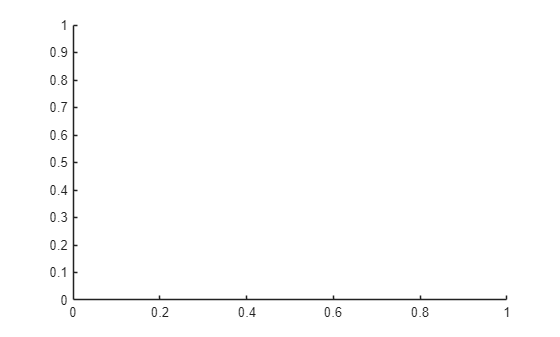

p =   plotlyfig with properties:

           data: {22×1 cell}
         layout: [1×1 struct]
         frames: {}
            url: ''
          error: []
        message: []
       UserData: [1×1 struct]
    PlotOptions: [1×1 struct]


layout.title = '<b>P. Larvae Y25747 Fern</b>';
% layout.title = 'Experimental data in Paenibacillus Larvae strain Y3650 with phage Fern';
layout.titlefont = struct('size', 45); % Set title font size and make it bold

%%%%%%%%%%%%%%%%%%%
layout.legend.font.size = 30;
layout.xaxis.title = 'Time (min)';
layout.xaxis.titlefont.size = 40;
layout.xaxis.tickfont.size = 35;
layout.yaxis.title = 'Cell density (OD600)';
layout.yaxis.titlefont.size = 40;
layout.yaxis.tickfont.size = 35;
%%%%%%%%%%%%%%%%%%%
layout.width = 1800; % required
layout.height = 1200; % required
layout.margin.l = 170;
layout.margin.b = 120;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
p = plotlyfig; % initalize an empty figure object
p.data = data;
p.layout = layout;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
p.PlotOptions.FileName = 'Y25747_Fern_dataset'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Create a standalone HTML file
html_file = plotlyoffline(p);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    